# Analytische Näherungslösung

### 1. Bewegungsgleichung und Kleinwinkelnäherung

Die vollständige Gleichung lautet $\ddot{\varphi} +\frac{g}{l}\sin (\varphi )=0$. Für kleine Auslenkungen gilt die Näherung $\sin (\varphi )\approx \varphi$ (Kleinwinkelnäherung). Die zu lösende homogene lineare Differentialgleichung 2. Ordnung lautet:


$$\ddot{\varphi} (t)+\frac{g}{l}\varphi (t)=0$$


### 2. Lösung der linearen Differentialgleichung

Lösen erfolgt klassisch per Exponentialansatz: $\varphi (t)=e^{\lambda t} ,~~\dot{\varphi} (t)=\lambda e^{\lambda t} ,~~\ddot{\varphi} (t)=\lambda^2 e^{\lambda t}$ 


$$e^{\lambda x} \left(\lambda^2 +\frac{g}{l}\right)=0$$


Da $e^{\lambda t} \not= 0$, folgt die charakteristische Gleichung


$$\lambda^2 +\frac{g}{l}=0\Longrightarrow \lambda^2 =-\frac{g}{l}$$


Daraus ergeben sich die rein imaginären Eigenwerte:


$$\lambda_{1,2} =\pm i\sqrt{\frac{g}{l}}$$


Damit ergibt sich die allgemeine Lösung:


$$\varphi (t)=c_1 \cos (\omega t)+c_2 \sin (\omega t),~~~~\omega =\sqrt{\frac{g}{l}}$$


### 3. Anfangsbedingungen

Das Pendel wird aus der Ruhe mit der Anfangsauslenkung $\varphi_0$ aus der Ruhe losgelassen:


$$\varphi (0)=c_1 \cos (0)+c_2 \sin (0)=c_1 \Rightarrow ~~c_1 =\varphi (0)=\varphi_0$$



$$\dot{\varphi} (t)=-c_1 \omega \sin (\omega t)+c_2 \omega \cos (\omega t)~~\dot{\varphi} (0)=c_2 \omega ~~\Rightarrow ~~c_2 =0$$


Die analytische Lösung für das Auslenken und Loslassen lautet:


$$\varphi (t)=\varphi_0 \cos (\omega t)$$


### 4. Periodendauer analytisch bestimmen

Vergleicht man dies mit der allgemeinen Schwingungsgleichung $\varphi (t)=\varphi_0 \cos (\omega t)$, so identifizieren wir die **Eigenkreisfrequenz**:


$$\omega =\sqrt{\frac{g}{l}}$$
 

Daraus lässt sich nun die Periodendauer  (die Zeit für eine vollständige Hin- und Herschwingung) berechnen:

$T_0 =\frac{2\pi }{\omega }$ = 19,8692 Sekunden

# Numerische Näherungslösung

Für die numerische Lösung in MATLAB wird die Differentialgleichung zweiter Ordnung in ein System zweier Differentialgleichungen erster Ordnung überführt. Dabei ergibt sich für das linearisierte Pendel:


$$\begin{array}{l}
y_1 =\varphi ,~~~~y_2 =\dot{\varphi} \\
{\dot{y} }_1 =y_2 ,~~~~{\dot{y} }_2 =-\frac{g}{l}\,y_1 
\end{array}$$


Dieses System wird mit den Anfangsbedingungen $\varphi (0)=\varphi_0$ und $\dot{\varphi} (0)=0$ numerisch integriert.

clear; clc; close all;

g = 9.81; % Erdbeschleunigung in m/s²
s = 0.1; % in s^(-2)
l = g / s; % Pendellänge ( 98,1m )
omega = sqrt(g / l); % Eigenkreisfrequenz
T_analytisch = 2 * pi / omega; % analytisch Periodendauer
phi_0 = deg2rad(1); % Startwinkel
tspan = [0 100*T_analytisch]; % 0 bis 100 Perioden
y0 = [phi_0; 0]; % Startzustand als Vektor (Start aus Ruhe)


[t, y] = ode45(@(t,y) pendulum_ode(t,y,g,l), tspan, y0);
% Ausgabe: t Vektor mit Zeitpunkten
%          y Matrix: y(:,1) = phi(t)
%                    y(:,2) = Ableitung von phi(t)

### Periodendauer mittels Nulldurchgang

Zusätzlich wird die Periodendauer über die Nulldurchgänge der Auslenkung bestimmt. Die Zeitpunkte der Nulldurchgänge werden durch  Interpolation zwischen zwei aufeinanderfolgenden Stützstellen mit Vorzeichenwechsel bestimmt:


$$t_1 =t_i ,~~t_2 =t_{i+1} ,~~~~\varphi_1 =\varphi (t_i ),~~\varphi_2 =\varphi (t_{i+1} )$$
 


$$t_0 =t_i -\varphi (t_i )\,\frac{t_{i+1} -t_i }{\varphi (t_{i+1} )-\varphi (t_i )}$$
 

Da aufeinanderfolgende Nulldurchgänge einer harmonischen Schwingung einer halben Periodendauer entsprechen, ergibt sich $T=2\Delta t$

phi = y(:,1);
k = find(phi(1:end-1) .* (phi(2:end)) < 0); % Bilde produkte benachbarter Werte und prüfe < 0
% find holt die indexliste
% Zeitpunkte der Nullstellen mittels Interpolation
z = t(k) - (phi(k) .* ((t(k+1) - t(k)) ./ (phi(k+1) - phi(k))));
% Aufeinanderfolgende Nulldurchgänge sind halbe Perioden
T_Nulldurchgang= 2*mean(diff(z));

### Periodendauer mittels findpeaks

Die Periodendauer wird zunächst über die zeitlichen Abstände aufeinanderfolgender Maxima der Auslenkung bestimmt. 


$$\varphi_{i-1} <\varphi_i >\varphi_{i+1}$$
 

Der Mittelwert dieser Abstände ergibt die numerische Periodendauer $T_{\textrm{findpeaks}}$

% Höhe der Peaks, Position der Peaks
[pks, locs] = findpeaks(phi, t);
% Abstände zwischen den Peaks rechnen + mean
T_findpeaks = mean(diff(locs));

### Plot, Hilfsfunktion, Ergebnisse aufrufen

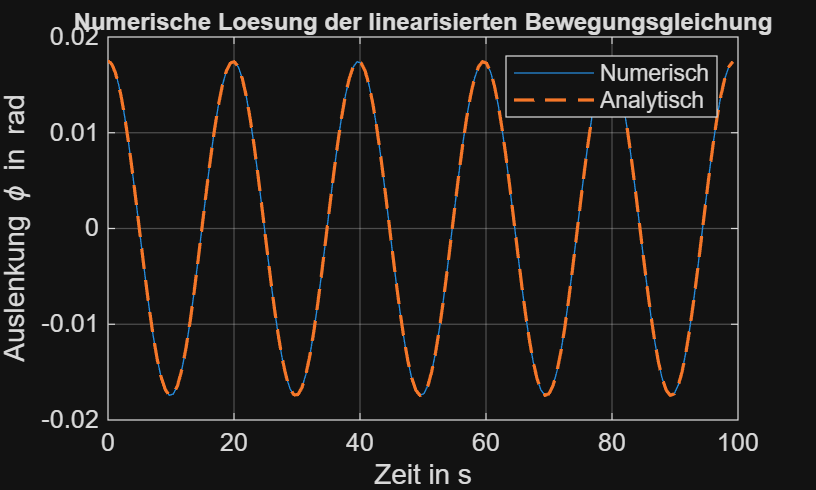

t_plot = t <= 5*T_analytisch;
figure;
plot(t(t_plot), phi(t_plot)); grid on;
xlabel("Zeit in s");
ylabel("Auslenkung \phi in rad");
phi_analytisch = phi_0*cos(omega*t(t_plot));
hold on
plot(t(t_plot), phi_analytisch, '--', 'LineWidth', 1.2)
legend('Numerisch','Analytisch')

title('Numerische Loesung der linearisierten Bewegungsgleichung', 'FontSize', 9);


fprintf('Analytisch ermittelte Periodendauer T: %.4f s\n', T_analytisch);

Analytisch ermittelte Periodendauer T: 19.8692 s


fprintf('Numerisch (Nulldurchgang) ermittelte Periodendauer T: %.4f s\n', T_Nulldurchgang);

Numerisch (Nulldurchgang) ermittelte Periodendauer T: 19.8673 s


fprintf('Numerisch (findpeaks) ermittelte Periodendauer T: %.4f s\n', T_findpeaks);

Numerisch (findpeaks) ermittelte Periodendauer T: 19.8635 s




function dydt = pendulum_ode(t,y,g,l)
    phi = y(1); % y(:,1) = phi(t)
    phi_dydt = y(2); % y(:,2) = Ableitung von phi(t)
    dydt = [phi_dydt; -(g/l) * phi];
end